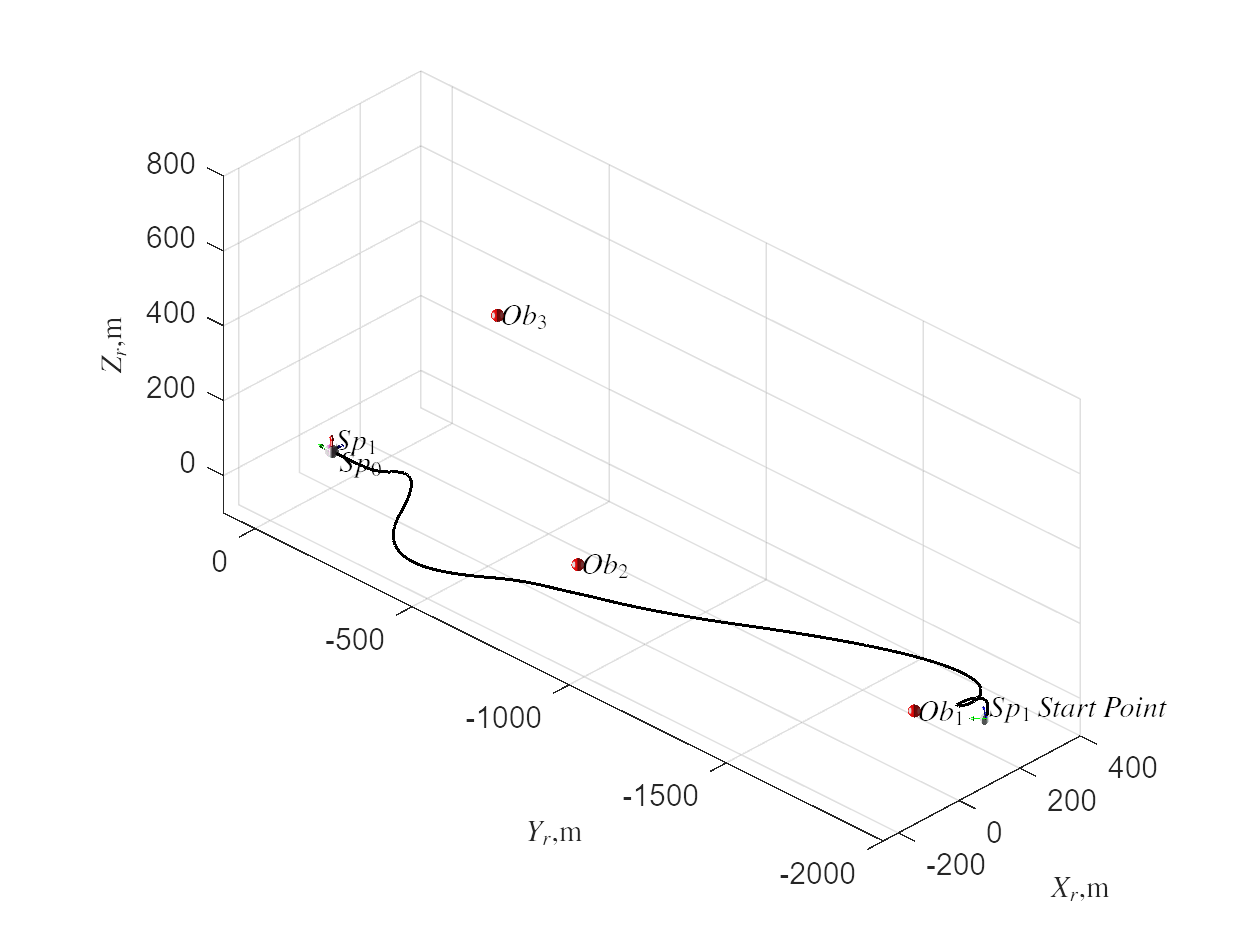

load x_1.mat
load y_1.mat
load z_1.mat

load SO2S1.mat
load SO2Ob1.mat
load SO2Ob2.mat
load SO2Ob3.mat

t= x_1(1,:);
x_1 = x_1(2:4,:);
y_1 = y_1(2:4,:);
z_1 = z_1(2:4,:);

SO2S1 = SO2S1(2:4,:);
SO2Ob1 = SO2Ob1(2:4,:);
SO2Ob2 = SO2Ob2(2:4,:);
SO2Ob3 = SO2Ob3(2:4,:);

step = 20/0.02;
for i=1:step:30001
    virtualSP(SO2Ob1(:,i),15,[1,0,0]);
    text(SO2Ob1(1,i)+15,SO2Ob1(2,i)+15,SO2Ob1(3,i)-15,'\( {Ob_{1}}\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP(SO2Ob2(:,i),15,[1,0,0]);
    text(SO2Ob2(1,i)+15,SO2Ob2(2,i)+15,SO2Ob2(3,i)-15,'\( {Ob_{2}}\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP(SO2Ob3(:,i),15,[1,0,0]);
    text(SO2Ob3(1,i)+15,SO2Ob3(2,i)+15,SO2Ob3(3,i)-15,'\( {Ob_{3}}\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP(SO2S1(:,1),15,[0.5,0.54,0.53]);
    text(SO2S1(1,1)+15,SO2S1(2,1)+15,SO2S1(3,1)+15,'\( {Sp_{1}}~Start~Point\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP([0,0,0],15,[1,0.38,0.75]);
    text(-15,-30,-15,'\( {Sp_{0}}\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP(SO2S1(:,i),15,[0.5,0.54,0.53]);
    text(SO2S1(1,i)+15,SO2S1(2,i)+15,SO2S1(3,i)+15,'\( {Sp_{1}}\)','Interpreter','latex','FontSize',10);
    hold on
    AxisP(SO2S1(:,1),15,x_1(:,1),y_1(:,1),z_1(:,1));
    hold on
    AxisP(SO2S1(:,end),15,x_1(:,end),y_1(:,end),z_1(:,end));
    hold on
    AxisP(SO2S1(:,i),15,x_1(:,i),y_1(:,i),z_1(:,i));
    hold on
    plot3(SO2S1(1,1:i),SO2S1(2,1:i),SO2S1(3,1:i),'-k','LineWidth',1)
    daspect([1,1,1])
    % axis([SO2S1(1,i)-250 SO2S1(1,i)+250 SO2S1(2,i)-200 SO2S1(2,i)+200 SO2S1(3,i)-150 SO2S1(3,i)+400])
    axis([-250 +400 -2000 +100 -100 +800])
    set(gca,'FontSize',10); % 设置文字大小，同时影响坐标轴标注、图例、标题等。
    set(get(gca,'XLabel'),'FontSize',10);%图上文字为8 point或小5号
    set(get(gca,'YLabel'),'FontSize',10)
    set(get(gca,'ZLabel'),'FontSize',10)
    xlabel('\(X_{r}\),m','Interpreter','latex','FontSize',10);
    ylabel('\(Y_{r}\),m','Interpreter','latex','FontSize',10);
    zlabel('\(Z_{r}\),m','Interpreter','latex','FontSize',10);
    view([-46 31])
    pause(0.1)
    hold off
end

  figure()
    virtualSP(SO2S1(:,1),15,[0.5,0.54,0.53]);
    text(SO2S1(1,1)+15,SO2S1(2,1)+100,SO2S1(3,1)+50,'\( {Sp_{1}}~start\)','Interpreter','latex','FontSize',16);
    hold on
    virtualSP(SO2Ob1(:,end),15,[1,0,0]);
    text(SO2Ob1(1,end)+15,SO2Ob1(2,end)+50,SO2Ob1(3,end)+30,'\( {Ob_{1}}\)','Interpreter','latex','FontSize',16);
    hold on
    virtualSP(SO2Ob2(:,end),15,[1,0,0]);
    text(SO2Ob2(1,end)+15,SO2Ob2(2,end)-15,SO2Ob2(3,end)+30,'\( {Ob_{2}}\)','Interpreter','latex','FontSize',16);
    hold on
    virtualSP(SO2Ob3(:,end),15,[1,0,0]);
    text(SO2Ob3(1,end)+15,SO2Ob3(2,end)-15,SO2Ob3(3,end)+30,'\( {Ob_{3}}\)','Interpreter','latex','FontSize',16);
    hold on
    virtualSP([0;0;0],15,[1,0.38,0.75]);
    text(20,-20,20,'\( {Sp_{1}}~ end\)','Interpreter','latex','FontSize',16);
    hold on
    AxisP(SO2S1(:,1),15,x_1(:,1),y_1(:,1),z_1(:,1));
    hold on
    AxisP(SO2S1(:,end),15,x_1(:,end),y_1(:,end),z_1(:,end));
    hold on
%     AxisP(SO2S1(:,i),7.5,x_1(:,i),y_1(:,i),z_1(:,i));
%     hold on
    plot3(SO2S1(1,1:end),SO2S1(2,1:end),SO2S1(3,1:end),'-k','LineWidth',2)
    hold on
    plot3(SO2Ob2(1,1:end),SO2Ob2(2,1:end),SO2Ob2(3,1:end),'--r','LineWidth',2)
    daspect([1,1,1])
%     axis([SO2S1(1,i)-30 SO2S1(1,i)+30 SO2S1(2,i)-100 SO2S1(2,i)+100 SO2S1(3,i)-30 SO2S1(3,i)+30])
    set(gca,'FontSize',16); % 设置文字大小，同时影响坐标轴标注、图例、标题等。
    set(get(gca,'XLabel'),'FontSize',16);%图上文字为8 point或小5号
    set(get(gca,'YLabel'),'FontSize',16)
    set(get(gca,'ZLabel'),'FontSize',16)
    xlabel('\(x_{b,0}\), m','Interpreter','latex','FontSize',24);
    ylabel('\(y_{b,0}\), m','Interpreter','latex','FontSize',24);
    zlabel('\(z_{b,0}\), m','Interpreter','latex','FontSize',24);    
    view([-16 25])
%%
    figure()
    virtualSP(SO2S1(:,1),15,[0.5,0.54,0.53]);
    text(SO2S1(1,1)+15,SO2S1(2,1)+15,SO2S1(3,1)+15,'\( {Sp_{1}}~start\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP(SO2Ob1(:,end),15,[1,0,0]);
    text(SO2Ob1(1,end)+15,SO2Ob1(2,end)+15,SO2Ob1(3,end)-15,'\( {Ob_{1}}\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP(SO2Ob2(:,end),15,[1,0,0]);
    text(SO2Ob2(1,end)+15,SO2Ob2(2,end)+15,SO2Ob2(3,end)-15,'\( {Ob_{2}}\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP(SO2Ob3(:,end),15,[1,0,0]);
    text(SO2Ob3(1,end)+15,SO2Ob3(2,end)+15,SO2Ob3(3,end)-15,'\( {Ob_{3}}\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP([0;0;0],15,[1,0.38,0.75]);
    text(20,-20,20,'\( {Sp_{1}}~ end\)','Interpreter','latex','FontSize',10);
    hold on
    AxisP(SO2S1(:,1),15,x_1(:,1),y_1(:,1),z_1(:,1));
    hold on
    AxisP(SO2S1(:,end),15,x_1(:,end),y_1(:,end),z_1(:,end));
    hold on
%     AxisP(SO2S1(:,i),7.5,x_1(:,i),y_1(:,i),z_1(:,i));
%     hold on
    plot3(SO2S1(1,1:end),SO2S1(2,1:end),SO2S1(3,1:end),'-k','LineWidth',1)
    hold on
    plot3(SO2Ob2(1,1:end),SO2Ob2(2,1:end),SO2Ob2(3,1:end),'--r','LineWidth',1)
    daspect([1,1,1])
%     axis([SO2S1(1,i)-30 SO2S1(1,i)+30 SO2S1(2,i)-100 SO2S1(2,i)+100 SO2S1(3,i)-30 SO2S1(3,i)+30])
    set(gca,'FontSize',10); % 设置文字大小，同时影响坐标轴标注、图例、标题等。
    set(get(gca,'XLabel'),'FontSize',10);%图上文字为8 point或小5号
    set(get(gca,'YLabel'),'FontSize',10)
    set(get(gca,'ZLabel'),'FontSize',10)
    xlabel('\(X_{r}\),m','Interpreter','latex','FontSize',10);
    ylabel('\(Y_{r}\),m','Interpreter','latex','FontSize',10);
    zlabel('\(Z_{r}\),m','Interpreter','latex','FontSize',10);
    zlim([-30,650])
    view([0 0])
%     axis([50 150 -2100 -1950 40 140])
%%
        figure()
    virtualSP(SO2S1(:,1),15,[0.5,0.54,0.53]);
    text(SO2S1(1,1)+15,SO2S1(2,1)+200,SO2S1(3,1)+100,'\( {Sp_{1}}~start\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP(SO2Ob1(:,end),15,[1,0,0]);
    text(SO2Ob1(1,end)+15,SO2Ob1(2,end)+15,SO2Ob1(3,end)-15,'\( {Ob_{1}}\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP(SO2Ob2(:,end),15,[1,0,0]);
    text(SO2Ob2(1,end)+15,SO2Ob2(2,end)+15,SO2Ob2(3,end)-15,'\( {Ob_{2}}\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP(SO2Ob3(:,end),15,[1,0,0]);
    text(SO2Ob3(1,end)+15,SO2Ob3(2,end)+15,SO2Ob3(3,end)-15,'\( {Ob_{3}}\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP([0;0;0],15,[1,0.38,0.75]);
    text(20,-20,20,'\( {Sp_{1}}~ end\)','Interpreter','latex','FontSize',10);
    hold on
    AxisP(SO2S1(:,1),15,x_1(:,1),y_1(:,1),z_1(:,1));
    hold on
    AxisP(SO2S1(:,end),15,x_1(:,end),y_1(:,end),z_1(:,end));
    hold on
%     AxisP(SO2S1(:,i),7.5,x_1(:,i),y_1(:,i),z_1(:,i));
%     hold on
    plot3(SO2S1(1,1:end),SO2S1(2,1:end),SO2S1(3,1:end),'-k','LineWidth',1)
    hold on
    plot3(SO2Ob2(1,1:end),SO2Ob2(2,1:end),SO2Ob2(3,1:end),'--r','LineWidth',1)
    daspect([1,1,1])
%     axis([SO2S1(1,i)-30 SO2S1(1,i)+30 SO2S1(2,i)-100 SO2S1(2,i)+100 SO2S1(3,i)-30 SO2S1(3,i)+30])
    set(gca,'FontSize',10); % 设置文字大小，同时影响坐标轴标注、图例、标题等。
    set(get(gca,'XLabel'),'FontSize',10);%图上文字为8 point或小5号
    set(get(gca,'YLabel'),'FontSize',10)
    set(get(gca,'ZLabel'),'FontSize',10)
    xlabel('\(X_{r}\),m','Interpreter','latex','FontSize',10);
    ylabel('\(Y_{r}\),m','Interpreter','latex','FontSize',10);
    zlabel('\(Z_{r}\),m','Interpreter','latex','FontSize',10);
    zlim([-30,650])
     view([-90 0])
     %%
             figure()
    virtualSP(SO2S1(:,1),15,[0.5,0.54,0.53]);
    text(SO2S1(1,1)+15,SO2S1(2,1)+200,SO2S1(3,1)+100,'\( {Sp_{1}}~start\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP(SO2Ob1(:,end),15,[1,0,0]);
    text(SO2Ob1(1,end)+15,SO2Ob1(2,end)+15,SO2Ob1(3,end)-15,'\( {Ob_{1}}\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP(SO2Ob2(:,end),15,[1,0,0]);
    text(SO2Ob2(1,end)+15,SO2Ob2(2,end)+15,SO2Ob2(3,end)-15,'\( {Ob_{2}}\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP(SO2Ob3(:,end),15,[1,0,0]);
    text(SO2Ob3(1,end)+15,SO2Ob3(2,end)+15,SO2Ob3(3,end)-15,'\( {Ob_{3}}\)','Interpreter','latex','FontSize',10);
    hold on
    virtualSP([0;0;0],15,[1,0.38,0.75]);
    text(20,-20,20,'\( {Sp_{1}}~ end\)','Interpreter','latex','FontSize',10);
    hold on
    AxisP(SO2S1(:,1),15,x_1(:,1),y_1(:,1),z_1(:,1));
    hold on
    AxisP(SO2S1(:,end),15,x_1(:,end),y_1(:,end),z_1(:,end));
    hold on
%     AxisP(SO2S1(:,i),7.5,x_1(:,i),y_1(:,i),z_1(:,i));
%     hold on
    plot3(SO2S1(1,1:end),SO2S1(2,1:end),SO2S1(3,1:end),'-k','LineWidth',1)
    hold on
    plot3(SO2Ob2(1,1:end),SO2Ob2(2,1:end),SO2Ob2(3,1:end),'--r','LineWidth',1)
    daspect([1,1,1])
%     axis([SO2S1(1,i)-30 SO2S1(1,i)+30 SO2S1(2,i)-100 SO2S1(2,i)+100 SO2S1(3,i)-30 SO2S1(3,i)+30])
    set(gca,'FontSize',10); % 设置文字大小，同时影响坐标轴标注、图例、标题等。
    set(get(gca,'XLabel'),'FontSize',10);%图上文字为8 point或小5号
    set(get(gca,'YLabel'),'FontSize',10)
    set(get(gca,'ZLabel'),'FontSize',10)
    xlabel('\(X_{r}\),m','Interpreter','latex','FontSize',10);
    ylabel('\(Y_{r}\),m','Interpreter','latex','FontSize',10);
    zlabel('\(Z_{r}\),m','Interpreter','latex','FontSize',10);
    zlim([-30,650])
    view([-90 90])